clear;clc;

w=[0.10,0.14,0.23,0.37,0.60,0.95,1.53,2.44,3.91,6.25,10.0];%rad/s
Lw=[-0.049,-0.102,-0.258,-0.638,-1.507,-3.270,-6.315,-10.81,-16.69,-23.65,-31.27];%dB
phi=[-9.72,-14.12,-22.45,-35.35,-54.56,-81.25,-115.5,-157.2,-207.8,-271.7,-358.9];%度

设传递函数为：$G\left(s\right)=\frac{{\mathrm{Ke}}^{-\tau s} }{\left(T_1 s+1\right)\left(T_2 s+1\right)\;}$

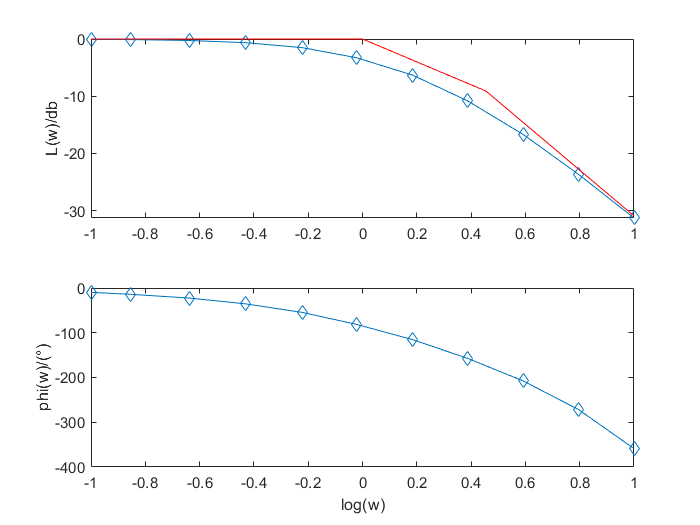


x=log10(w); %横坐标转化为对数坐标
figure(1);
%% 对数幅频图
subplot(2,1,1)
plot(x,Lw,'d-');
ylabel('L(w)/db');

w1=1; 
w2=2.85;
%第一段 
L1=[0,0];
x1=[-1,0];
hold on
plot(x1,L1,'r');
%第二段
x2=[0,log10(2.85)];
L2=-20*x2;
hold on
plot(x2,L2,'r');
%第三段
x3=[log10(2.85),1];
L3=-40*x3+20*log10(2.85);
hold on
plot(x3,L3,'r');
%% 对数相频图
subplot(2,1,2)
plot(x,phi,'d-');
xlabel('log(w)');
ylabel('phi(w)/(°)');

% %% 求开环传递函数
K=1

K = 1

T1=1/w1

T1 = 1

T2=1/w2

T2 = 0.3509

phi1=spline(w,phi,1)

phi1 = -84.6921

phi2=spline(w,phi,2.85)

phi2 = -172.9450

%估计的滞后时间
t1=(-phi1-atan(T1*w1)-atan(T2*w1))*pi/(w1*180)

t1 = 1.4586

t2=(-phi2-atan(T1*w2)-atan(T2*w2))*pi/(w2*180)

t2 = 1.0467

t=(t1+t2)/2 

t = 1.2527

传递函数为：$\mathrm{G}{\left(\mathrm{s}\right)}=\frac{e^{-1.2527s} }{\left(s+1\right)\left(0.3509s+1\right)}$